# Experiment Set #38.

The goal of the experiment is to identify how robust optimization can be done to find minimal zonotope representation.

% Add experiments and functions to the path
include_fcns('MPT3','YALMIP')

All Libraries successfully added to path.


Creating a set that we want to enclose with an arbitrary zonotope.

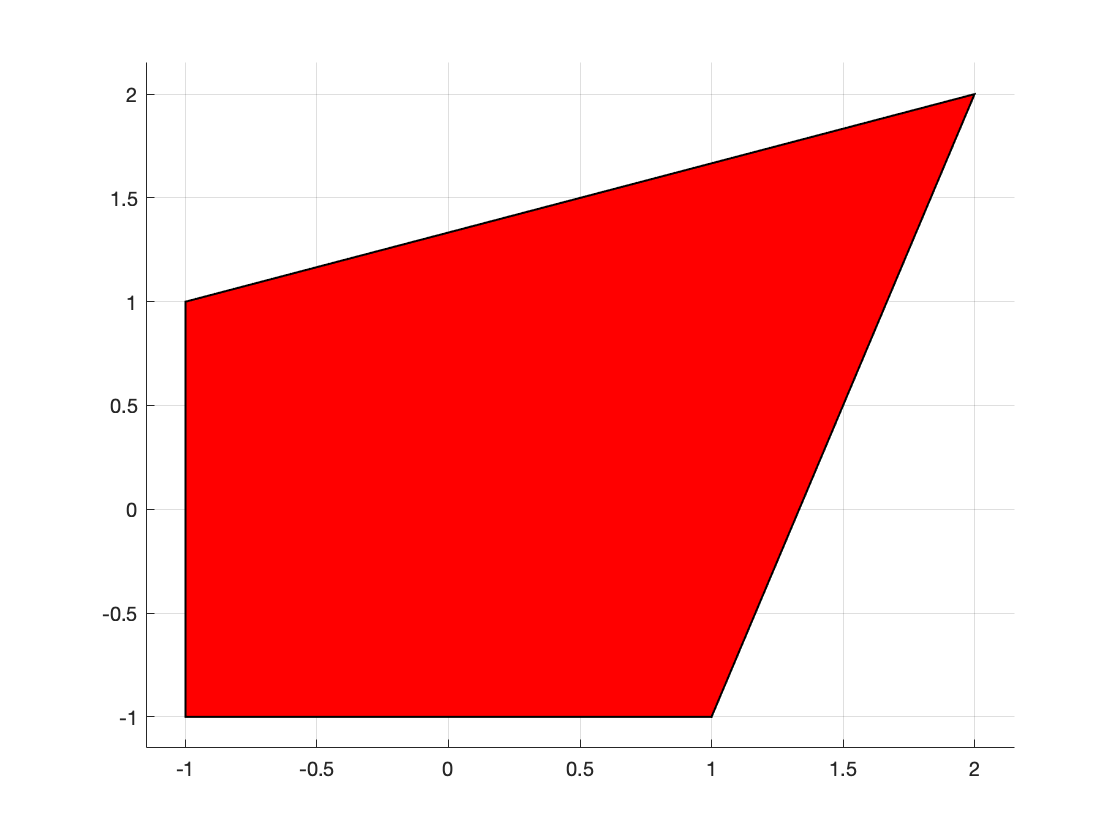

P_e = Polyhedron('A', [ 0 , -1; -1, 0; -(1/3), 1; 3, -1 ], ...
                 'b', [1;1;(4/3);4]);
figure;
plot(P_e)

Create a zonotope template. We will control the scaling of the generators to control its size in optimization. A traditional zonotope might be:


$$$\mathcal{Z} = \left\{ x \in \mathbb{R}^2 \left| \exists \theta \; \text{ s.t. } x = c + G\theta \wedge (|\theta_i| \leq 1 \; \forall i) \right. \right\}$
$$


And so we seek to find a modified zonotope of the following form:


$$$\mathcal{Z}_{\alpha} = \left\{ x \in \mathbb{R}^2 \left| \exists \theta \; \text{ s.t. } x = c + G\theta \wedge (|\theta_i| \leq \alpha \; \forall i) \right. \right\}$
$$


Z_t.c = zeros(2,1);
%Z_t.G = [ [1;0] [0;1] ];
%Z_t.G = [ [1;1]*(1/sqrt(2)), [0;1] ]
Z_t.G = [ [2;2], [1;-1] [0;1] ];

num_g = size(Z_t.G,2);

With all of this, we can state the formal problem that we want to solve:


$$\begin{array}{rl}
  \underset{\alpha}{\text{min}} & \alpha \\
  \text{subject to} & \mathcal{P}_w \subseteq \mathcal{Z}_{\alpha}
\end{array} $$


This can be stated in the following way:


$$\begin{array}{rl}
  \underset{\begin{array}{c} \alpha \in \mathbb{R} \end{array}}{\text{min}} & \alpha \\
  \text{subject to} & \exists \theta \text{ such that } w = c + G \theta \text{ for any } w \in \mathcal{P}_w
\end{array} $$


In a more mathematical construction:


$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R} \\
  	\end{array} }{\text{min}} & \alpha \\
  \text{subject to} & \forall w \in \mathcal{P}_w & \\
  					& \quad \exists \theta = f(w) \in \mathbb{B}(\alpha) \text{ s.t. } & w = c + G \theta \\
\end{array} $$


where $f:\mathcal{P}_w \mapsto \mathbb{B}(\alpha)$ is a mapping and $\mathbb{B}(\mu)$ is the set of all two dimensional vectors with infinity norm less than $\mu$. This is in fact a robust optimization problem and I think that we can apply the following reasoning to get it into a more easily understood form:


$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R} \\
  		\underline{\theta},\overline{\theta} \in \mathbb{B}(\alpha)
  	\end{array} }{\text{min}} & \alpha \\
  \text{subject to} & (\Pi^{(1)})^\top b \leq \overline{\theta} + G^\dagger c & \\
  					& A^\top \Pi^{(1)} = (G^\dagger)\top & \\
  					& (\Pi^{(2)})^\top b \leq -\underline{\theta} - (G^\dagger) c \\
  					& A^\top \Pi^{(2)}_i = (-(G^\dagger))^\top & \\
  					& \Pi^{(j)} \geq 0 & \forall j \in \{1,2 \} \\
\end{array} $$


A derivation for this form is shown after the following code snippet implementing the optimization.

%Define Optimization Variables
alpha = sdpvar(1,1,'full');
theta_t1 = sdpvar(num_g,1,'full');
theta_t2 = sdpvar(num_g,1,'full');
p1 = sdpvar(size(P_e.A,1),num_g,'full');
p2 = sdpvar(size(P_e.A,1),num_g,'full');

%Create Objective
objective = alpha;

%Create Constraints
equal_constrs = [p1'*P_e.b <= theta_t1 + pinv(Z_t.G)*Z_t.c] + ...
                [p2'*P_e.b <= -theta_t2 - pinv(Z_t.G)*Z_t.c];
dual_equal_constrs = [];
dual_equal_constrs = [P_e.A'*p1 == (pinv(Z_t.G))'] + ...
                     [P_e.A'*p2 == (-pinv(Z_t.G))'];
                 
dual_pos_constrs = [p1 >= 0] + [p2 >= 0];

%
inf_norm_constr = [ theta_t1 <= alpha ] + [-theta_t1 <= alpha] + ...
                  [ theta_t2 <= alpha ] + [-theta_t2 <= alpha];

%Optimize
ops = sdpsettings('verbose',1);
optim0 = optimize(equal_constrs+dual_equal_constrs+dual_pos_constrs+inf_norm_constr, ...
			objective, ...
			ops);

      0: obj =  -1.000000000e+06  infeas =  1.500e+07 (0)
*    16: obj =   1.000000000e+06  infeas =  0.000e+00 (0)
*    17: obj =   9.523809524e-01  infeas =  0.000e+00 (0)


if optim0.problem ~= 0
    disp(['Optimization failed with "problem" value: ' num2str(optim0.problem)])
else
    disp('Optimization seems to have been successful.')
    disp(['alpha = ' num2str(value(alpha))])
end

Optimization seems to have been successful.


alpha = 0.95238



%Optimal Scaling factor
sf = value(alpha)

sf = 0.9524

### Method 1 Derivation

In a more mathematical construction:


$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R} \\
  	\end{array} }{\text{min}} & \alpha \\
  \text{subject to} & \forall w \in \mathcal{P}_w & \\
  					& \quad \exists \theta = f(w) \in \mathbb{B}(\alpha) \text{ s.t. } & w = c + G \theta \\
\end{array} $$


where $f:\mathcal{P}_w \mapsto \mathbb{B}(\alpha)$ is a mapping and $\mathbb{B}(\mu)$ is the set of all two dimensional vectors with infinity norm less than $\mu$. This is in fact a robust optimization problem and I think that we can apply the following reasoning to get it into a more easily understood form:


$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R} \\
  	\end{array} }{\text{min}} & \alpha \\
  \text{subject to} & \forall w \in \mathcal{P}_w & \\
  					& \quad \exists \theta_1 = \theta_2 = f(w) \in \mathbb{B}(\alpha) \text{ s.t. } & w \leq c + G \theta_1 \\
  					& 																				& w \geq c + G \theta_2 \\
\end{array} $$


Now, because $\theta_1,\theta_2 \in \mathbb{B}(\alpha)$, we know that there exists an element $\overline{\theta} \in \mathbb{B}(\alpha)$ such that $\overline{\theta} \geq \theta_i \; \forall i \in \{1,2 \}$ where $\geq$ for these vectors is the elementwise inequality. Similarly, there also exists an element $\underline{\theta} \in \mathbb{B}(\alpha)$ such that $\underline{\theta} \leq \theta_i \; \forall i \in \{1,2 \}$. This means that we can change the "there exists" constraint by the following logic:


$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R} \\
  	\end{array} }{\text{min}} & \alpha \\
  \text{subject to} & \forall w \in \mathcal{P}_w & \\
  					& \quad \exists \theta_1 = \theta_2 = f(w) \in \mathbb{B}(\alpha) \text{ s.t. } & G^\dagger (w - c) \leq \theta_1 \\
  					& 																				& G^\dagger (w-c)  \geq \theta_2 \\
\end{array} $$



$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R} \\
  	\end{array} }{\text{min}} & \alpha \\
  \text{subject to} & \forall w \in \mathcal{P}_w & \\
  					& \quad \exists \theta_1 = \theta_2 = f(w) \in \mathbb{B}(\alpha) \text{ s.t. } & G^\dagger (w - c) \leq \theta_1 \leq \overline{\theta} \\
  					& 																				& G^\dagger (w-c)  \geq \theta_2 \geq \underline{\theta}\\
\end{array} $$


and then 


$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R} \\
  	\end{array} }{\text{min}} & \alpha \\
  \text{subject to} & \forall w \in \mathcal{P}_w & \\
  					& \quad G^\dagger (w - c) \leq \overline{\theta} & \\
  					& \quad G^\dagger (w-c)  \geq \underline{\theta} & \\
\end{array} $$


Because the two bounding thetas are not functions of $w$, but are instead bounds that exist for all $\theta$ in the range of $f(\cdot)$, we no longer have the constraint that they must be unique for each choice of $w$. Then, the following optimization can be solved when $\overline{\theta}$ and $\underline{\theta}$ are unknown:


$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R} \\
  		\underline{\theta},\overline{\theta} \in \mathbb{B}(\alpha)
  	\end{array} }{\text{min}} & \alpha \\
  \text{subject to} & \forall w \in \mathcal{P}_w & \\
  					& \quad G^\dagger (w - c) \leq \overline{\theta} & \\
  					& \quad G^\dagger (w-c)  \geq \underline{\theta} & \\
\end{array} $$


This can be written in the following form when the constraints are taken to be scalar valued:


$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R} \\
  		\underline{\theta},\overline{\theta} \in \mathbb{B}(\alpha)
  	\end{array} }{\text{min}} & \alpha \\
  \text{subject to} & \forall w \in \mathcal{P}_w & \\
  					& \quad (G^\dagger)_i (w - c) \leq \overline{\theta}_i & \forall i \in [1,n_\mathcal{Z}] \\
  					& \quad (G^\dagger)_i (w-c)  \geq \underline{\theta}_i & \forall i \in [1,n_\mathcal{Z}] \\
\end{array} $$


By rearranging the signs of some inequalities, we obtain:


$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R} \\
  		\underline{\theta},\overline{\theta} \in \mathbb{B}(\alpha)
  	\end{array} }{\text{min}} & \alpha \\
  \text{subject to} & \forall w \in \mathcal{P}_w & \\
  					& \quad (G^\dagger)_i (w - c) \leq \overline{\theta}_i & \forall i \in [1,n_\mathcal{Z}] \\
  					& \quad -(G^\dagger)_i (w-c)  \leq -\underline{\theta}_i & \forall i \in [1,n_\mathcal{Z}] \\
\end{array} $$


where $(G^\dagger)_i$ is the $i^{th}$ row of the pseudoinverse of $G$ and $n_{\mathcal{Z}}$ is the number of generators in the zonotope $\mathcal{Z}$. Now, let us robustify each of these constraints individually (it doesn't matter how we do it now, because they are uncoupled constraints):


$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R} \\
  		\underline{\theta},\overline{\theta} \in \mathbb{B}(\alpha)
  	\end{array} }{\text{min}} & \alpha \\
  \text{subject to} & \left [
  						\begin{array}{rl}
  							\underset{w}{\text{max}} & (G^\dagger)_i w \\
  							\text{subject to} & A w \leq b
  						\end{array}
  						\right ] \leq \overline{\theta}_i + (G^\dagger)_i c & \forall i \in [1,n_\mathcal{Z}] \\
  					& \left [
  						\begin{array}{rl}
  							\underset{w}{\text{max}} & -(G^\dagger)_i w \\
  							\text{subject to} & A w \leq b
  						\end{array}
  						\right ] \leq -\underline{\theta}_i - (G^\dagger)_i c & \forall i \in [1,n_\mathcal{Z}] \\
\end{array} $$



$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R} \\
  		\underline{\theta},\overline{\theta} \in \mathbb{B}(\alpha)
  	\end{array} }{\text{min}} & \alpha \\
  \text{subject to} & \left [
  						\begin{array}{rl}
  							\underset{w}{\text{max}} & w^\top ((G^\dagger)_i)^\top \\
  							\text{subject to} & A w \leq b
  						\end{array}
  						\right ] \leq \overline{\theta}_i + (G^\dagger)_i c & \forall i \in [1,n_\mathcal{Z}] \\
  					& \left [
  						\begin{array}{rl}
  							\underset{w}{\text{max}} & w^\top (-(G^\dagger)_i)^\top \\
  							\text{subject to} & A w \leq b
  						\end{array}
  						\right ] \leq -\underline{\theta}_i - (G^\dagger)_i c & \forall i \in [1,n_\mathcal{Z}] \\
\end{array} $$


Now, by the straight forward robust linear program trick we know:


$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R} \\
  		\underline{\theta},\overline{\theta} \in \mathbb{B}(\alpha)
  	\end{array} }{\text{min}} & \alpha \\
  \text{subject to} & \left [
  						\begin{array}{rl}
  							\underset{\pi^{(1)}_i}{\text{min}} & (\pi^{(1)}_i)^\top b \\
  							\text{subject to} 	& A^\top \pi^{(1)}_i = ((G^\dagger)_i)^\top \\
  												& \pi^{(1)}_i \geq 0 
  						\end{array}
  						\right ] \leq \overline{\theta}_i + (G^\dagger)_i c & \forall i \in [1,n_\mathcal{Z}] \\
  					& \left [
  						\begin{array}{rl}
  							\underset{\pi^{(2)}_i}{\text{min}} & (\pi^{(2)}_i)^\top b \\
  							\text{subject to} & A^\top \pi^{(2)}_i = (-(G^\dagger)_i)^\top \\
  												& \pi^{(2)}_i \geq 0 
  						\end{array}
  						\right ] \leq -\underline{\theta}_i - (G^\dagger)_i c & \forall i \in [1,n_\mathcal{Z}] \\
\end{array} $$


Then, by removing the minimizations we achive:


$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R} \\
  		\underline{\theta},\overline{\theta} \in \mathbb{B}(\alpha)
  	\end{array} }{\text{min}} & \alpha \\
  \text{subject to} & (\pi^{(1)}_i)^\top b \leq \overline{\theta}_i + (G^\dagger)_i c & \forall i \in [1,n_\mathcal{Z}] \\
  					& A^\top \pi^{(1)}_i = ((G^\dagger)_i)^\top & \forall i \in [1,n_\mathcal{Z}] \\
  					& \pi^{(1)}_i \geq 0 & \forall i \in [1,n_\mathcal{Z}] \\
  					& (\pi^{(2)}_i)^\top b \leq -\underline{\theta}_i - (G^\dagger)_i c & \forall i \in [1,n_\mathcal{Z}] \\
  					& A^\top \pi^{(2)}_i = (-(G^\dagger)_i)^\top & \forall i \in [1,n_\mathcal{Z}]\\
  					& \pi^{(2)}_i \geq 0 & \forall i \in [1,n_\mathcal{Z}] \\
\end{array} $$


And then by concatenating vector constraints into matrix constraints we can define the following problem:


$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R} \\
  		\underline{\theta},\overline{\theta} \in \mathbb{B}(\alpha)
  	\end{array} }{\text{min}} & \alpha \\
  \text{subject to} & (\Pi^{(1)})^\top b \leq \overline{\theta} + G^\dagger c & \\
  					& A^\top \Pi^{(1)} = (G^\dagger)\top & \\
  					& (\Pi^{(2)})^\top b \leq -\underline{\theta} - (G^\dagger) c \\
  					& A^\top \Pi^{(2)}_i = (-(G^\dagger))^\top & \\
  					& \Pi^{(j)} \geq 0 & \forall j \in \{1,2 \} \\
\end{array} $$


### Method 2

The second method takes advantage of the following form of the optimization problem.


$$\begin{array}{rll}
  \underset{\alpha \in \mathbb{R}, \; \theta \in \mathbb{R}^2}{\text{min}} & \alpha & \\
  \text{subject to} & | \theta_i | \leq \alpha & \forall i \in {1,2} \\ & w \leq c + G \theta & \forall w \in \mathcal{P}_w \\
  & -w \leq -c - G \theta & \forall w \in \mathcal{P}_w
\end{array} $$


By robustifying the optimization where the two inequality constraints on $w$ are combined, we can obtain the following optimization problem:


$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R}, \\
  		\theta^{(1)},\theta^{(2)} \in \mathbb{R}^2 \\
  		\Pi^{(1)},\Pi^{(2)} \in \mathbb{R}^{4 \times n_{\mathcal{Z}}} \\
  	\end{array}}{\text{min}} & \alpha & \\
  \text{subject to} & \| \theta^{(i)} \|_{\infty} \leq \alpha & \forall i \in {1,2} \\
  					& \left [
  						\begin{array}{c}
  							\Pi^{(1)} \\
  							\Pi^{(2)}	
  						\end{array}
  					  \right]^\top b \leq \left[ \begin{array}{c} I \\ -I \end{array} \right] (G^\dagger c + \theta) \\
  					& A^\top \left [ \begin{array}{c} \Pi^{(1)} \\ \Pi^{(2)} \end{array} \right ] = \left [ \begin{array}{c} (G^\dagger)^\top \\ -(G^\dagger)^\top \end{array} \right ] \\
  					& \Pi^{(i)} \geq 0 & \forall i \in \{ 1,2 \} \\
\end{array} $$


clear alpha theta_t1 p1

%Define Optimization Variables
alpha = sdpvar(1,1,'full');
theta_t1 = sdpvar(num_g,1,'full');
p1 = sdpvar(size(P_e.A,1),2*num_g,'full');

%Create Objective
objective = alpha;

%Create Constraints
equal_constrs = [p1'*P_e.b <= [eye(num_g);-eye(num_g)]*(theta_t1 + pinv(Z_t.G)*Z_t.c)];
                
pinv(Z_t.G)'

ans =     0.2857    0.4286   -0.1429
    0.1905   -0.3810    0.2381


size([(pinv(Z_t.G))'; ( -pinv(Z_t.G))'])

ans =      4     3


size(P_e.A'*p1)

ans =      2     6


dual_equal_constrs = [];
dual_equal_constrs = [P_e.A'*p1([1:size(P_e.A,1)],[1:num_g]) == (pinv(Z_t.G))'];
dual_equal_constrs = dual_equal_constrs + ...
                    [P_e.A'*p1([1:size(P_e.A,1)],[num_g+1:2*num_g]) == ( -pinv(Z_t.G))'];
                 
dual_pos_constrs = [p1 >= 0];

%
inf_norm_constr = [ theta_t1 <= alpha ] + [-theta_t1 <= alpha];

%Optimize
ops = sdpsettings('verbose',1);
optim0 = optimize(equal_constrs+dual_equal_constrs+dual_pos_constrs+inf_norm_constr, ...
			objective, ...
			ops);

      0: obj =  -1.000000000e+06  infeas =  9.000e+06 (0)
     10: obj =   4.761904762e-01  infeas =  1.810e+00 (0)
glp_simplex: unable to recover undefined or non-optimal solution


if optim0.problem ~= 0
    disp(['Optimization failed with "problem" value: ' num2str(optim0.problem)])
else
    disp('Optimization seems to have been successful.')
    disp(['alpha = ' num2str(value(alpha))])
end

Optimization failed with "problem" value: 1



%Optimal Scaling factor
sf = value(alpha)

sf = 0

The steps in making this transformation are shown below:

The second method takes advantage of the following form of the optimization problem.


$$\begin{array}{rll}
  \underset{\alpha \in \mathbb{R}, \; \theta \in \mathbb{R}^2}{\text{min}} & \alpha & \\
  \text{subject to} & | \theta_i | \leq \alpha & \forall i \in {1,2} \\ & w \leq c + G \theta & \forall w \in \mathcal{P}_w \\
  & -w \leq -c - G \theta & \forall w \in \mathcal{P}_w
\end{array} $$


One thing that you can do without stretching the imagination too much, is imagining the bottom two inequalities are combined:


$$\begin{array}{rll}
  \underset{\alpha \in \mathbb{R}, \; \theta \in \mathbb{R}^2}{\text{min}} & \alpha & \\
  \text{subject to} & | \theta_i | \leq \alpha & \forall i \in {1,2} \\
  					& \left [ \begin{array}{c} I \\ -I \end{array} \right ] G^\dagger w \leq \left [ \begin{array}{c} I \\ -I \end{array} \right ] (G^\dagger c + \theta) & \forall w \in \mathcal{P}_w \\
\end{array} $$


This can be reinterpreted as the following series of inequalities:


$$\begin{array}{rll}
  \underset{\alpha \in \mathbb{R}, \; \theta \in \mathbb{R}^2}{\text{min}} & \alpha & \\
  \text{subject to} & | \theta_i | \leq \alpha & \forall i \in {1,2} \\
  					& (G^\dagger)_i w \leq (G^\dagger)_i c + \theta_i & \forall w \in \mathcal{P}_w, \; \forall i \in [1,n_\mathcal{Z}] \\
  					& -(G^\dagger)_i w \leq  -(G^\dagger)_i c + \theta_i & \forall w \in \mathcal{P}_w, \; \forall i \in [1,n_\mathcal{Z}] \\
\end{array} $$


where $(G_i^\dagger)_i$ is the $i^{th}$ row of the pseudoinverse of $G$ and $n_\mathcal{Z}$ is the number of generators in the zonotope $\mathcal{Z}$. The system is now very in a form where robustification can be quickly applied:


$$\begin{array}{rll}
  \underset{\alpha \in \mathbb{R}, \; \theta \in \mathbb{R}^2}{\text{min}} & \alpha & \\
  \text{subject to} & | \theta_i | \leq \alpha & \forall i \in {1,2} \\
  					& w^\top ((G^\dagger)_i)^\top  \leq (G^\dagger)_i c + \theta_i & \forall w \in \mathcal{P}_w, \; \forall i \in [1,n_\mathcal{Z}] \\
  					& w^\top (-(G^\dagger)_i)^\top \leq  -(G^\dagger)_i c + \theta_i & \forall w \in \mathcal{P}_w, \; \forall i \in [1,n_\mathcal{Z}] \\
\end{array} $$


Robustification applied:


$$\begin{array}{rll}
  \underset{\alpha \in \mathbb{R}, \; \theta \in \mathbb{R}^2}{\text{min}} & \alpha & \\
  \text{subject to} & | \theta_i | \leq \alpha & \forall i \in {1,2} \\
  					& \left[
  						\begin{array}{rl}
  							\underset{w}{\text{max}} & w^\top ((G^\dagger)_i)^\top \\
  							\text{subject to} & A w \leq b \\
  						\end{array}
  						\right]
  						\leq (G^\dagger)_i c + \theta_i & \forall i \in [1,n_\mathcal{Z}] \\
  					& \left[
  						\begin{array}{rl}
  							\underset{w}{\text{max}} & w^\top (-(G^\dagger)_i)^\top \\
  							\text{subject to} & A w \leq b \\
  						\end{array}
  						\right]
  						\leq -(G^\dagger)_i c + \theta_i & \forall i \in [1,n_\mathcal{Z}] \\
\end{array} $$


**This step seems problematic because **$\theta_i$** is held constant while **$w$** is allowed to vary**. But let's follow through with the computation:


$$\begin{array}{rll}
  \underset{\alpha \in \mathbb{R}, \; \theta^{(1)},\theta^{(2)} \in \mathbb{R}^2}{\text{min}} & \alpha & \\
  \text{subject to} & \| \theta^{(i)} \|_{\infty} \leq \alpha & \forall i \in {1,2} \\
  					& \left[
  						\begin{array}{rl}
  							\underset{w}{\text{min}} & (\pi^{(1)}_i)^\top b \\
  							\text{subject to} 	& A^\top \pi^{(1)}_i = ((G^\dagger)_i)^\top \\
  												& \pi^{(1)}_i \geq 0 \\
  						\end{array}
  						\right]
  						\leq (G^\dagger)_i c + \theta_i & \forall i \in [1,n_\mathcal{Z}] \\
  					& \left[
  						\begin{array}{rl}
  							\underset{w}{\text{min}} & (\pi^{(2)}_i)^\top b \\
  							\text{subject to} 	& A^\top \pi^{(2)}_i = -((G^\dagger)_i)^\dagger \\
  												& \pi^{(2)}_i \geq 0
  						\end{array}
  						\right]
  						\leq -(G^\dagger)_i c + \theta_i & \forall i \in [1,n_\mathcal{Z}] \\
\end{array} $$


By reinterpreting the inequality:


$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R}, \\
  		\theta^{(1)},\theta^{(2)} \in \mathbb{R}^2 \\
  		\pi^{(1)},\pi^{(2)} \in \mathbb{R}^{n_\mathcal{Z}}
  	\end{array}}{\text{min}} & \alpha & \\
  \text{subject to} & \| \theta^{(i)} \|_{\infty} \leq \alpha & \forall i \in {1,2} \\
  					& (\pi^{(1)}_i)^\top b \leq (G^\dagger)_i c + \theta_i & \forall i \in [1,n_\mathcal{Z}] \\
  					& A^\top \pi^{(1)}_i = ((G^\dagger)_i)^\top & \forall i \in [1,n_\mathcal{Z}] \\
  					& \pi^{(1)}_i \geq 0 & \forall i \in [1,n_\mathcal{Z}] \\
  					& (\pi^{(2)}_i)^\top b \leq -(G^\dagger)_i c + \theta_i & \forall i \in [1,n_\mathcal{Z}] \\
  					& A^\top \pi^{(2)}_i = -((G^\dagger)_i)^\dagger & \forall i \in [1,n_\mathcal{Z}] \\
  					& \pi^{(2)}_i \geq 0 & \forall i \in [1,n_\mathcal{Z}] \\
\end{array} $$


By concatenating the many inequalities, we can consolidate the constraints into the following:


$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R}, \\
  		\theta^{(1)},\theta^{(2)} \in \mathbb{R}^2 \\
  		\Pi^{(1)},\Pi^{(2)} \in \mathbb{R}^{4 \times n_{\mathcal{Z}}} \\
  	\end{array}}{\text{min}} & \alpha & \\
  \text{subject to} & \| \theta^{(i)} \|_{\infty} \leq \alpha & \forall i \in {1,2} \\
  					& (\Pi^{(1)})^\top b \leq G^\dagger c + \theta & \\
  					& A^\top \Pi^{(1)} = (G^\dagger)^\top & \\
  					& \Pi^{(i)} \geq 0 & \forall i \in \{ 1,2 \} \\
  					& (\Pi^{(2)})^\top b \leq -G^\dagger c - \theta & \\
  					& A^\top \Pi^{(2)} = -(G^\dagger)^\top & \\
\end{array} $$


If we want to combine the dual variable inequalities we get the following:


$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R}, \\
  		\theta^{(1)},\theta^{(2)} \in \mathbb{R}^2 \\
  		\Pi^{(1)},\Pi^{(2)} \in \mathbb{R}^{4 \times n_{\mathcal{Z}}} \\
  	\end{array}}{\text{min}} & \alpha & \\
  \text{subject to} & \| \theta^{(i)} \|_{\infty} \leq \alpha & \forall i \in {1,2} \\
  					& \left [
  						\begin{array}{c}
  							\Pi^{(1)} \\
  							\Pi^{(2)}	
  						\end{array}
  					  \right]^\top b \leq \left[ \begin{array}{c} I \\ -I \end{array} \right] (G^\dagger c + \theta) \\
  					& A^\top \left [ \begin{array}{c} \Pi^{(1)} & \Pi^{(2)} \end{array} \right ] = \left [ \begin{array}{c} (G^\dagger)^\top, & -(G^\dagger)^\top \end{array} \right ] \\
  					& \Pi^{(i)} \geq 0 & \forall i \in \{ 1,2 \} \\
\end{array} $$


### Method 3: Enumerating Vertices

This method will implement the robust constraint by enumerating all vertices in the polytope $\mathcal{P}_w$:


$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R} \\
  	\end{array} }{\text{min}} & \alpha \\
  \text{subject to} & \forall w \in \mathcal{P}_w & \\
  					& \quad \exists \theta_1 = \theta_2 = f(w) \in \mathbb{B}(\alpha) \text{ s.t. } & G^\dagger (w - c) \leq \theta_1 \leq \alpha \mathbf{ \underline{\mathbb{1}} } \\
  					& 																				& G^\dagger (w-c)  \geq \theta_2 \geq -\alpha \mathbf{ \underline{\mathbb{1}} \\
\end{array} $$
 

When enumerating all vertices, the problem becomes:


$$\begin{array}{rll}
  \underset{
  	\begin{array}{c}
  		\alpha \in \mathbb{R} \\
  	\end{array} }{\text{min}} & \alpha \\
  \text{subject to} & G^\dagger (w^{(j)} - c) \leq \alpha \mathbf{ \underline{\mathbb{1}} } & \forall w^{(j)} \in \mathcal{V}(\mathcal{P}_w) \\
  					& G^\dagger (w^{(j)} - c) \geq -\alpha \mathbf{ \underline{\mathbb{1}} } & \forall w^{(j)} \in \mathcal{V}(\mathcal{P}_w) \\
\end{array} $$


where $\mathcal{V}(\mathcal{S})$ is the set of vertices for the polytope $\mathcal{S}$.

clear alpha theta_t1 p1

%Define Optimization Variables
alpha = sdpvar(1,1,'full');

%Find Corners in P_e
P_e.computeVRep();

%Create Objective
objective = alpha;

%Create Constraints
inf_norm_constr =[];
for vert_ind = 1:size(P_e.V,1)
    inf_norm_constr = inf_norm_constr + ...
                        [pinv(Z_t.G)*(P_e.V(vert_ind,:)' - Z_t.c) <= alpha] + ...
                        [pinv(Z_t.G)*(P_e.V(vert_ind,:)' - Z_t.c) >= -alpha];
end

%Optimize
ops = sdpsettings('verbose',1);
optim0 = optimize(inf_norm_constr, ...
			objective, ...
			ops);

~     0: obj =   9.523809524e-01  infeas =  0.000e+00


if optim0.problem ~= 0
    disp(['Optimization failed with "problem" value: ' num2str(optim0.problem)])
else
    disp('Optimization seems to have been successful.')
    disp(['alpha = ' num2str(value(alpha))])
end

Optimization seems to have been successful.


alpha = 0.95238



%Optimal Scaling factor
sf = value(alpha)

sf = 0.9524

## Problem 2

The problem statement is:

"if x is in a set (hyperbox or zonotope), what would be the smallest scaled set (hyperbox or zonotope) a linear transformation of x would live in"

clear alpha theta_t1 p1

%PRoblem Statement Parameters
M0 = 0.5;
A = magic(2);
b = [1;2];
n_x = 2;

x_polyt = Polyhedron('lb',ones(1,n_x)*(-M0),'ub',ones(1,n_x)*M0);

%Define Decision Variables
alpha = sdpvar(1,1,'full');
Pi_1 = sdpvar(size(x_polyt.b,1),size(A,1));
Pi_2 = sdpvar(size(x_polyt.b,1),size(A,1));

%Create Objective
obj = alpha;

constrs = [Pi_1'*x_polyt.b <= alpha*ones(n_x,1) - b ] + [x_polyt.A'*Pi_1 == A'] + [Pi_1 >= 0];
constrs = [Pi_2'*x_polyt.b <= alpha*ones(n_x,1) + b ] + [x_polyt.A'*Pi_2 == -A'] + [Pi_2 >= 0] + constrs;

%Optimize
ops = sdpsettings('verbose',1);
optim0 = optimize(  constrs, objective, ops);

      0: obj =  -1.000000000e+06  infeas =  4.000e+06 (0)
*     8: obj =  -1.000000000e+06  infeas =  0.000e+00 (0)



if optim0.problem ~= 0
    disp(['Optimization failed with "problem" value: ' num2str(optim0.problem)])
else
    disp('Optimization seems to have been successful.')
    disp(['alpha = ' num2str(value(alpha))])
end

Optimization seems to have been successful.


alpha = 5



%Optimal Scaling factor
sf = value(alpha)

sf = 5